# Planet trajectory prediction

t = 0:0.02:10; % time

x = cos(2*pi*t);
y = 2*sin(2*pi*t);
theta = pi/3;
R = [cos(theta) -sin(theta); sin(theta) cos(theta)];
xy = R * [x; y];

z = ones(1, length(t));
data = [xy; z];
p = 0.5;

mid_point = round((length(data) - 1) * p);
train_t = t(1:mid_point-1);
test_t = t(mid_point:end-1);

train_input = data(:, 1:mid_point);
train_output = data(:, 2:mid_point + 1);
test_input = data(:, mid_point:end - 1);
test_output = data(:, mid_point + 1:end, :);

## Construct the network

net = Network();

lID(1) = net.addLayer(1,                    'bias',     struct('nodeType', 'linear', 'leakageInit', 'constant', 'leakageVal', '1.0')); 
lID(2) = net.addLayer(size(train_input, 1), 'input',    struct('nodeType', 'linear', 'leakageInit', 'constant', 'leakageVal', '0.0'));
lID(3) = net.addLayer(size(train_output,1), 'output',   struct('nodeType', 'linear', 'leakageInit', 'constant', 'leakageVal', '1.0'));
lID(4) = net.addLayer(100,                  'layer',     struct('nodeType', 'tanh',   'leakageInit', 'constant', 'leakageVal', '0.5'));

net.setConnection(lID(2), lID(4), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 1.0));
net.setConnection(lID(2), lID(3), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 1.0));
net.setConnection(lID(1), lID(3), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 1.0));
net.setConnection(lID(1), lID(4), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 1.0));
net.setConnection(lID(4), lID(3), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 1.0));
net.setConnection(lID(4), lID(4), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 0.1));


%net.visualize();

## Train the network

boltrain = BatchOutputLayerTrain();
initLen = 100;
tic
x = boltrain.train(net, train_input, train_output, initLen, 'ridge1');
toc 

Elapsed time is 0.094304 seconds.


% figure, plot(x')

## Generate/Predict

tic
net.rememberStates();
y = net.generate(test_input);
net.recallStates();
toc 

Elapsed time is 0.035460 seconds.



disp(['RMSE: ', num2str(norm(y - test_output)/sqrt(length(y)))]);

RMSE: 2.1255


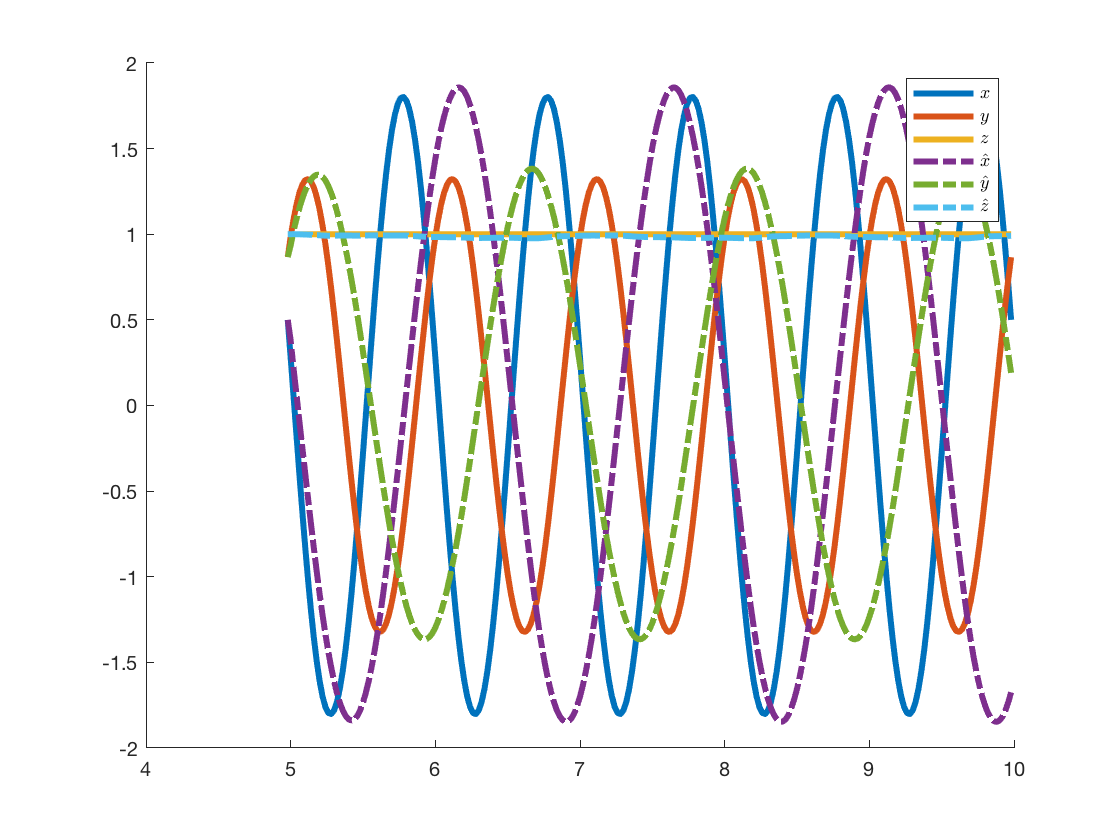

%disp(['NRMSE: ', num2str(NRMSE(y, test_output))]);

figure, hold on;
plot(test_t, test_output', 'linewidth', 3);
plot(test_t, y','-.', 'linewidth', 3);
legend({'$x$', '$y$', '$z$', '$\hat{x}$', '$\hat{y}$', '$\hat{z}$'}, 'interpreter', 'latex');

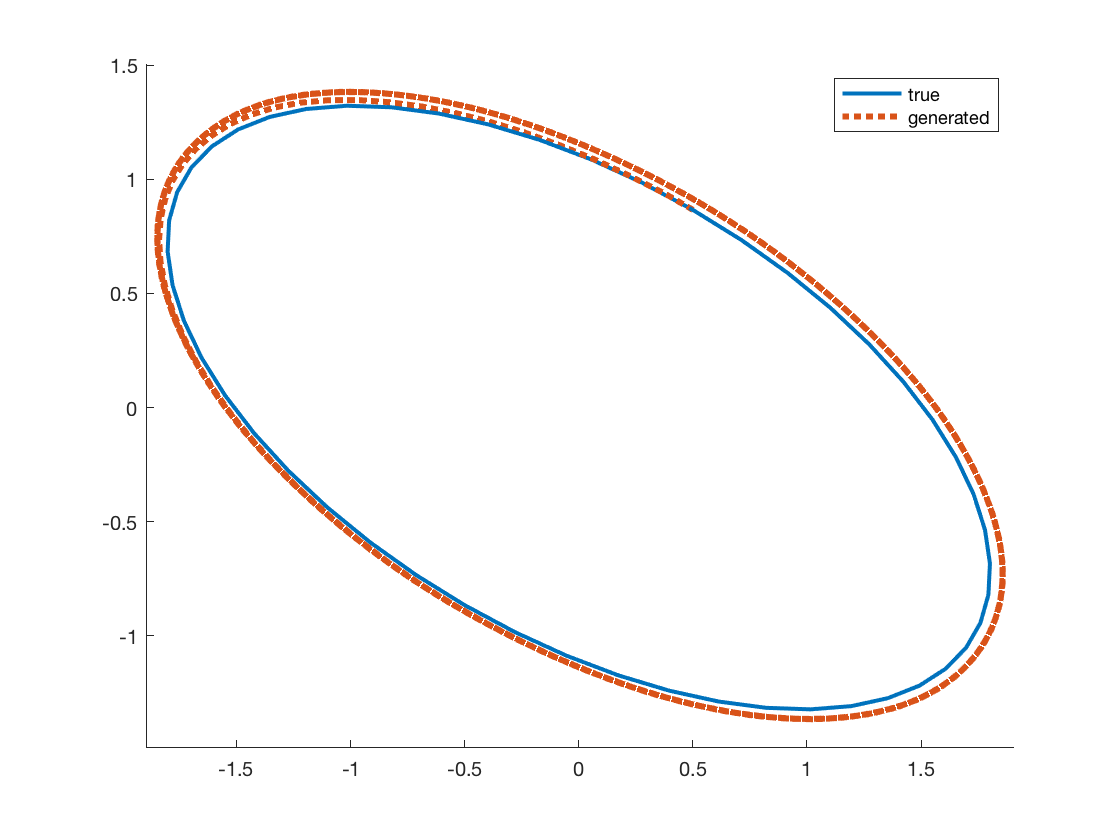


figure, hold on;
plot3(test_output(1,:), test_output(2,:), test_output(3,:), 'linewidth', 2);
plot3(y(1,:), y(2,:), y(3,:), ':', 'linewidth', 3);
legend({'true', 'generated'});
axis equal